clear all
filename = 'sample_tracking_video_raw.mp4';
% instantiate an instance of the MarkerTracking class using the raw video
% filename
track_instance = MarkerTracking(filename);

track_instance.read_frames_all();
% Alternatively one can open the video in an external media player, choose the start and end
% times to be tracked (in seconds), and use the read_frames_partial method with that
% time range to extract only those frames

% The next two lines read total number of frames and maximum image intensity to set up the
% sliders below
num_frames = size(track_instance.frames_gray,3);
max_intensity = max(track_instance.frames_gray(:));

% Tweak the image threshold value to ensure all the markers of interest get
% recognized. Then make sure the threshold value works for a few other
% frames in the duration
frame_num = 1

frame_num = 1

image_threshold = 135

image_threshold = 135

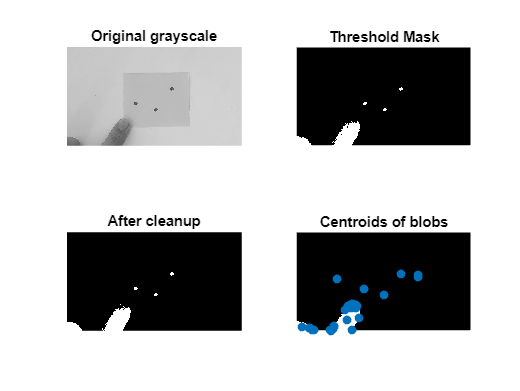

track_instance.tracking_overview(frame_num, image_threshold);

% Draw rectangles over region(s) that contain the marker(s) of interest
% using an interactive window
% After drawing the rectangle, right click on it and click on crop
track_instance.draw_inclusion_mask();
% Run this cell multiple times if there are multiple areas that need to
% be included

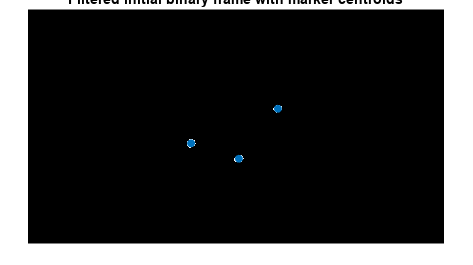

% Run this cell to apply the inclusion mask and threshold settings on the
% first frame in the stack. Verify that only the markers of interest are
% getting marked.
track_instance.tracking_initiation();

% Run this cell to track the markers recognized in the initiation stage
% over the length of the video, store the x and y coordinates and write mp4
% and gif files of tracking
[tracked_x_log, tracked_y_log] = track_instance.create_tracking_video('tracked');